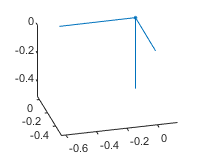

% 'out' is Simulink output variable.
P = transpose(out.P.Data);
tP = out.P.Time;
n = length(out.R.Data);
for i = 1:n
    R(:,:,i) =-1 * eye(3) * out.R.Data(:,:,i);
end
tR = out.R.Time;

[x,y,z,u,v,w] = genQuiver3Data(P,R);

for i=1:n
hold on
xi = repmat(x(i),[3, 1]);
yi = repmat(y(i),[3, 1]);
zi = repmat(z(i),[3, 1]);
ui = u(:,i);
vi = v(:,i);
wi = w(:,i);

q = quiver3(xi,yi,zi,ui,vi,wi);
q.Marker = '.';
q.MaxHeadSize = 0.1;
q.AutoScale = true;
q.AutoScaleFactor = 0.5;
axis equal
hold off

view([-14.761 25.877])

f = getframe
M(i) = f;

end